# LECTURE WEEK V. - EXERCISE

# DISCRETE-TIME FOURIER TRANSFORM AND DISCRETE FOURIER TRANSFORM

**Objectives:**

- Computing the DTFT and DFT of a discrete-time signal.

- Relate the discrete-­time Fourier Transform (DTFT) to the practical Discrete Fourier Transform (DFT).

- Understanding and interpretation of DFT results and spectra computed by using DFTs.

- Creating signals in the DFT domain.

- Estimation of the frequency of a harmonic component (cosine) in a signal.

## MATLAB Exercise V.1: Interpretation of the DFT coefficients

The following MATLAB exercise is important for understanding how to relate digital frequencies (i.e., the frequencies $\hat{\omega}$ or *f* of time-discrete (sampled) signals) to the numerical index of the arrays that you obtain after applying the DFT (`fft` function) on the array containing the signal samples. Understanding this relation is also needed for comparing DFT and DTFT results on the same signal. For that reason, this is the only MATLAB exercise that will be studied during the instruction session.

***A.***

Create 4 different signals $X[n] = cos(\hat{\omega}n)$ with $\hat{\omega} = 0, \frac{\pi}{4}, \frac{\pi}{2}, \text{and} \frac{3\pi}{4}$ (use 8 samples for each signal.) For each of these signals, compute the DFT using the MATLAB function `fft()`, and plot the magnitude of the spectrum (DFT coefficients) using the command `stem(abs(XX)``)`. What do you observe when the digital frequency $\hat{\omega}$ increases? Here is a code fragment to get your started.

N  = 8;
x1 = cos((0:N-1) * pi / 4);
X1 = fft(x1);
stem(abs(X1));

***Answer:***

***B.***

Complete the following table based on the result in part ***A***. What is the relation between the DFT coefficient index and the digital frequency $\hat{\omega}$? If you can’t find the answer, look ahead to part ***E*** of this Exercise).

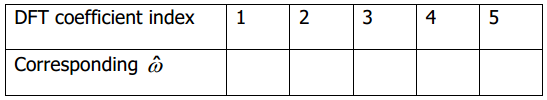

***Answer:***

***C.***

The above table has a maximum digital frequency $\hat{\omega}=\pi$. Why?

***Answer:***

***D.***

The MATLAB DFT (`fft` function) computes not only the spectrum for digital frequencies in the range $[0,\pi]$(namely coefficient 1 to 5 – or in general 1 to N/2+1), but 3 more coefficients (6, 7, and 8 – or in general N/2+2 to N). You may have observed that, for instance, the absolute_value(DFT coefficient 3) = absolute_value(DFT coefficient 7). This equality is due to the symmetry and periodicity of the DFT of real-valued signals. For the DTFT we know that

- $X(e^{j\hat{\omega}}) = X(e^j(\hat{\omega} + 2\pi)), \quad \text{periodic over }2\pi$.

- 
$$X(e^{j\hat{\omega}}) = X(e^{-j\hat{\omega}})^{*}, \quad \text{complex conjugated symmetry.}$$


If we now consider a frequency larger than $\pi$, say $\omega = \frac{3}{2}\pi$, we obtain:

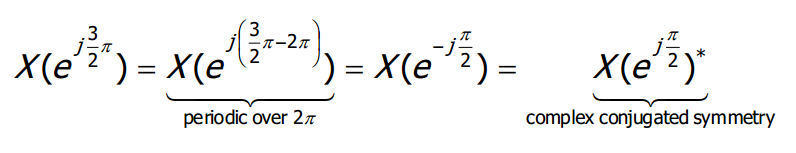

The frequency $\hat{\omega} = \frac{3}{2}\pi$ relates to the DFT coefficient number 7, which must therefore be equal to the complex conjugated DFT coefficient for $\hat{\omega} = \frac{1}{2}\pi$, which is DFT coefficient number 3. Explain the relation between DFT coefficient 2 and 8, and DFT coefficient 4 and 6 in a similar way.

***Answer:***

*Because of this symmetry for real-values signals, some fft implementations compute only the first N/2+1 DFT coefficients. The DFT of, for instance, as signal of 128 samples results in 65 DFT coefficients.*

***E.***

We now know how to relate the DFT coefficient index in a MATLAB vector to frequencies:

MATLAB vector index $k \rightarrow \hat{\omega} = (k-1)\frac{2\pi}{N}$.

Use this relation to make a stem-plot of the DFT of the 4 different signals $X[n] = cos(\hat{\omega}n)$ with $\hat{\omega} = 0, \frac{\pi}{4}, \frac{\pi}{2}, \text{and} \frac{3\pi}{4}$, and on the horizontal axis the *digital frequency* rather than the *index* of the DFT coefficient. For instance:

% Run code for the example of pi/2
N       = 8;
omegaxx = @(N) ((1:N)-1) * (2 * pi / N);
x2      = cos((0:N-1) * pi/2);
X2      = fft(x2);
stem(omegaxx(N), abs(X2));

The resulting figures with indices of the DFT coefficient (left figure) and digital frequency (right figure) on the horizontal axis are shown here for assisting you (for the case that $\hat{\omega} = \frac{\pi}{4}$).

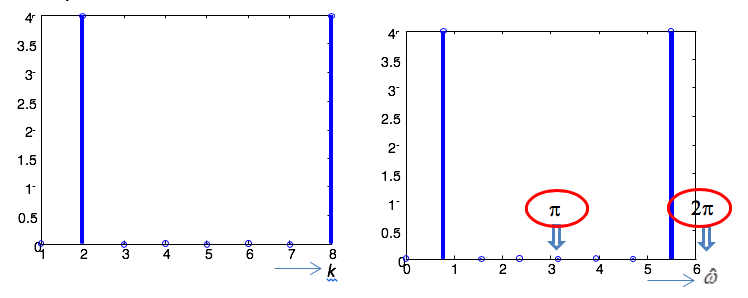

***Answer:***

***F.***

The signals considered so far had digital frequencies that exactly matched the frequency represented by one of the DFT coefficients according to the equation

MATLAB vector index $k \rightarrow \hat{\omega} = (k-1)\frac{2\pi}{N}$.

What happens if this is not the case? We consider the time-discrete signal $X[n] = cos(0.2\pi n)$ with 8 samples. Compute the DFT and plot the magnitude of the spectrum. Use digital frequencies rather than DFT coefficient indices on the horizontal axis.

***Answer:***

N       = 8;
omegaxx = @(N) ((1:N)-1) * (2 * pi / N);
x2      = cos((0:N-1) * 0.2 * pi);
X2      = fft(x2);
stem(omegaxx(N), abs(X2));

What is your conclusion?

***Answer:***

***G.***

Repeat part ***F*** for $X[n] = cos(\hat{\omega} n)$ with $\hat{\omega} = \frac{1}{16}\pi,\frac{2}{16}\pi, \frac{3}{16}\pi,\dots\pi$ and 8 samples (It may be handy to implement this as a script or function). 

***Answer:***

For which digital frequencies do you get (approximately) a single non-zero DFT coefficient?

***Answer:***

***H.***

Repeat part ***G***, in this case using a signal with 128 samples. Of course, the DFT representation uses 128 samples too. Compute the DFT and plot the magnitude of the DFT coefficients. Use digital frequencies rather than DFT coefficient indices on the horizontal axis. 

***Answer:***

What is your conclusion concerning the digital frequencies that can be represented by one non-zero DFT coefficient?

***Answer:***

Create $X[n] = cos(0.4n)$ with 128 samples. Compute the DFT and plot the magnitude of the DFT coefficients. Use digital frequencies rather than DFT coefficient indices on the horizontal axis. 

***Answer:***

What is your conclusion?

***Answer:***

## MATLAB Exercise V.2: Computing and visualizing the DFT

Consider the signal of MATLAB assignment ***IV.1 B***:


$$y[n] = 3 + e^{f 0.2 \pi n} + e^{-j 0.2 \pi n} - 7e^{f 0.7 \pi n} - 7e^{-f 0.7 \pi n - \pi / 3}$$


Generate the signal $y[n]$ with a sufficiently large number of samples, and compute the DFT of the signal using the MATLAB function `fft()`. 

***Answer:***

N = 128;
y = @(n) 3 + exp(1i*0.2*pi*n) + exp(-1i*0.2*pi*n) - 7*exp(1i*(pi/3)) ...
    * exp(1i*0.7*pi*n) - 7*exp(-1i*(pi/3)) * exp(-1i*0.7*pi*n);
freqaxis = @(k) (k-1) * ((2 * pi) / N);
yy = y(0:N-1);
YY = fft(yy);
stem(yy);

Plot the amplitude and phase spectrum. 

***Answer:***

figure;
stem(freqaxis(1:N), abs(YY))
title(['Magnitude of y with ' num2str(N) ' samples'])
figure;
stem(freqaxis(1:N), angle(YY))
title(['Phase of y with ' num2str(N) ' samples']);

Compare the outcome to the result of MATLAB assignment ***IV.1 B***. 

What is the conclusion? Notice how difficult it is to relate the phase spectrum directly to the phase terms in $y[n]$.

***Answer:***

## MATLAB Exercise V.3: Computing and visualizing the DFT

## (Theory exercise V.1E)

Use MATLAB to compute the DFT of the signal given in theory exercise ***V.1E***.


$$x[n] = \frac{3}{2}\delta[n] + \delta[n-1] + \frac{3}{2}\delta[n-2]$$


Compute the DFT of length N=8, N=16, N=64, N=256, N=1024. 

***Answer:***

% Example for N = 16
omega   = @(k) (k-1) * ((2 * pi)/N);
N       = 16;
xx      = zeros(1, N);
xx(1:3) = [1.5 1 1.5];
XX = fft(xx);

Print the resulting DFT coefficients. 

***Answer:***

% Based on the size of N
table = 'index    omega        DFT-coefficient\n';
table = [table '----------------------------------------\n'];
for k=1:N
    table = [table sprintf('%3i    %6.3f*pi    %7.4f + %7.4fj  \n', k, omega(k)/pi,...
        real(XX(k)), imag(XX(k)))];
end
fprintf(table);

Plotting the amplitude and the phase of the DFT coefficients. 

***Answer:***

% Based on the size of N
stem(omega(1:N), abs(XX))
title(['Magnitude of y with ' num2str(N) ' samples'])
figure;
stem(omega(1:N), angle(XX))
title(['Phase of y with ' num2str(N) ' samples']);

What is your conclusion concerning the length of the DFT used?

***Answer:***